# Normalizing Electricity Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

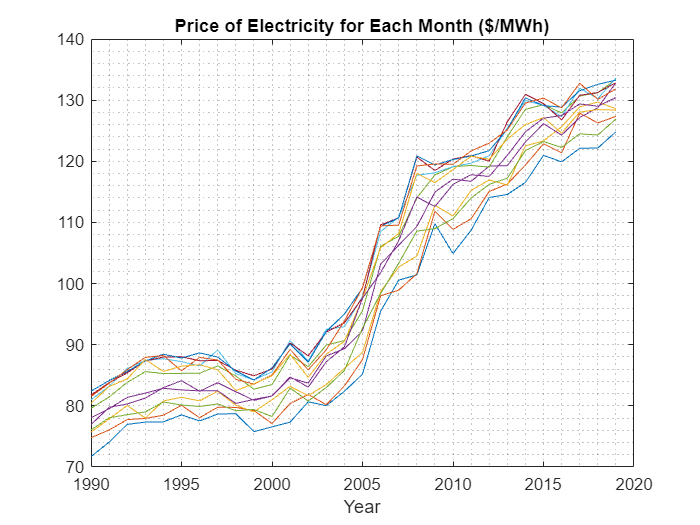

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');
price = readmatrix("./data/electricity.xlsx", Sheet='price');
dollar2019 = readmatrix("./data/electricity.xlsx", Sheet='dollar2019');

usage = com + res + ind;
price = price * 1000 / 100;
revenue = price .* usage;

plot(1990:2019, price')
grid minor
title("Price of Electricity for Each Month ($/MWh)")
xlabel("Year")

## Task 1

price2019 = price .* dollar2019;

This code creates a vector with the number of days in each month.

numDaysInMonth = [31 mean([28 28 28 29]) 31 30 31 30 31 31 30 31 30 31]'

numDaysInMonth =    31.0000
   28.2500
   31.0000
   30.0000
   31.0000
   30.0000
   31.0000
   31.0000
   30.0000
   31.0000


## Task 2

avgDailyUsage = usage ./ numDaysInMonth

avgDailyUsage = 1.0e+07 *

    0.7520    0.7531    0.7453    0.7596    0.8118    0.7980    0.8517    0.8606    0.8464    0.8879    0.9005       NaN    0.9115    0.9795    0.9911    0.9923    0.9813       NaN    1.0501       NaN    1.0683    1.0755    1.0010    1.0323       NaN    1.0613    1.0330    1.0242    1.1091    1.0414
    0.7293    0.7501    0.7742       NaN    0.8174    0.8193    0.8784    0.8589    0.8548    0.8601       NaN    0.9331    0.9048    0.9971    1.0117    0.9845    0.9927    1.0641    1.0776    1.0109    1.0541    1.0487    1.0136    1.0295    1.0911    1.0834    1.0483    0.9740       NaN    1.0279
    0.6669    0.6674    0.6853       NaN    0.7219    0.7379    0.7782    0.7599    0.7915    0.8138    0.8187    0.8400    0.8365    0.8835    0.8955    0.9203    0.9333    0.9384       NaN    0.9133    0.9415    0.9400    0.9133    0.9567    0.9734    0.9828    0.9200    0.9381    0.9563    0.9556
    0.6597    0.6631    0.6818    0.6948    0.7081    0.7152       NaN